# GEAR REDUCTION RATIO k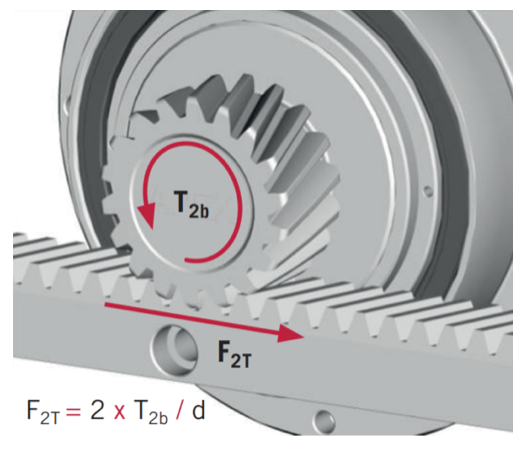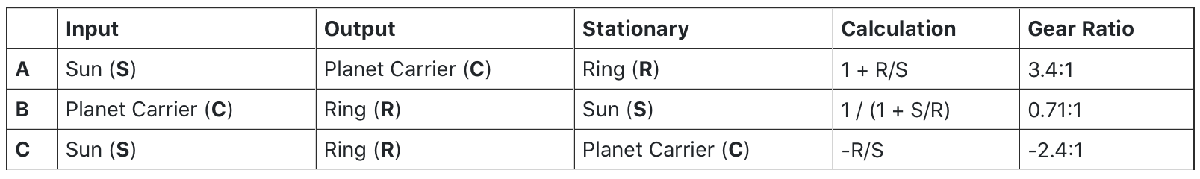

% racks and pinion (first picture)
% epi-cycloidal gear train
% planetary gear set (third picture)
syms k % k is reduction ratio
syms r_m r_l % r is radius or number of theet (obviusly thoots have same size)
syms theta_m theta_l % theta(t) is angular position
syms omega_m omega_l % omega(t) is angular velocity
syms T_l % torque of link
syms T_m % torque of motor

k = r_l / r_m

$$k = \frac{r_{l}}{r_{m}}$$

k = theta_m / theta_l

$$k = \frac{\theta_{m}}{\theta_{l}}$$

k = omega_m / omega_l % k = diff(theta_m) / diff(theta_l)

$$k = \frac{\omega_{m}}{\omega_{l}}$$

k = T_l / T_m

$$k = \frac{T_{l}}{T_{m}}$$


constraint = theta_m * r_m == theta_l * r_l

$$constraint = r_{m}\,\theta_{m}=r_{l}\,\theta_{l}$$

# GEAR RATIO k >> 1 (r_m << r_l)

% k>>1 typical case to have reductio, otherwise we have aplitude

find_r_l = r_l == k * r_m

$$find\_r\_l = r_{l}=\frac{T_{l}\,r_{m}}{T_{m}}$$

find_r_m = r_m == r_l / k

$$find\_r\_m = r_{m}=\frac{T_{m}\,r_{l}}{T_{l}}$$

# NO FRICTION

syms P_l % Power resultant on the link (required)
syms P_m % Power provided by motor
% ideal case: resultant power after trasmission is conservative
% power = force * speed = torque * angular speed
% torque = force * radius = inertia * angular acceleration
% angular speed = speed / radius

power_motor = P_l == diff(theta_l) * T_l 

$$power\_motor = P_{l}=T_{l}$$

power_link = P_m == diff(theta_m) * T_m

$$power\_link = P_{m}=T_{m}$$


ideal_case = P_l == P_m

$$ideal\_case = P_{l}=P_{m}$$


efficency = P_l/P_m % same to respect to the current P_out/P_in [%]

$$efficency = \frac{P_{l}}{P_{m}}$$

# MECHANICAL GEAR RESULTANT 

syms I_m I_l % inertia (every body has it's own inertia = sumOf(mass * radius^2)) 
% is the resistence to change in velocity (i.e. cilinder is 1/2*M*R^2)
syms F_m F_l % dissipative forces (friction)
syms f % f is the resultant force applied to the link

diving_torque = T_m % torque required to perform the task (unknown)

$$diving\_torque = T_{m}$$

reaction_torque = T_l % reaction torque relative to the link (known i.e. m*g*l*sinθ)

$$reaction\_torque = T_{l}$$

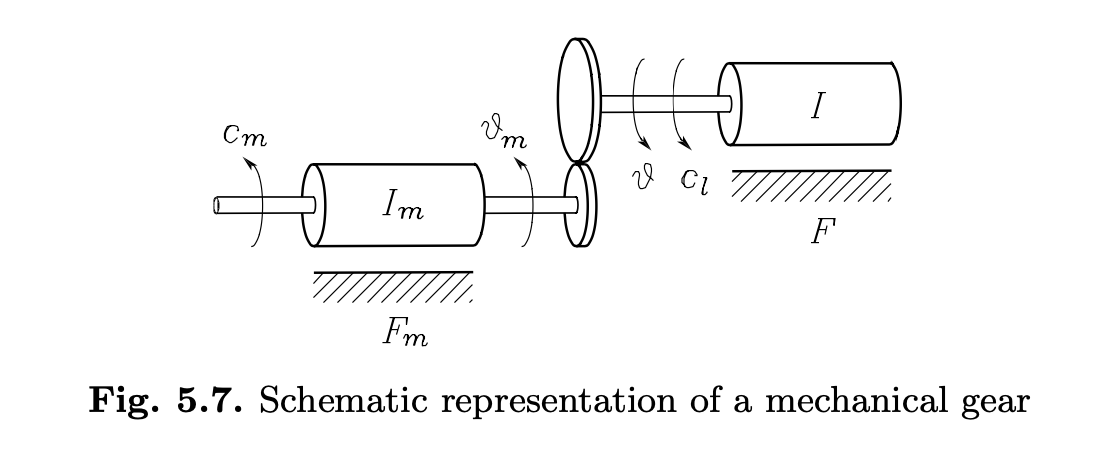

% here substitute reaction_torque, get the diving_torque_resultant,
% substitute with reaction_torque_resultant and get the value of diving_torque
% (required torque c_m, here T_m)

diving_torque_resultant_on_gear = f * r_l

$$diving\_torque\_resultant\_on\_gear = f\,r_{l}$$


reaction_torque_resultant_on_gear = f * r_m

$$reaction\_torque\_resultant\_on\_gear = f\,r_{m}$$


first_condition = T_m == I_m * diff(omega_m) + F_m * omega_m + f * r_m

$$first\_condition = T_{m}=I_{m}+F_{m}\,\omega_{m}+f\,r_{m}$$


second_condition = f * r_l == I_l * diff(omega_l) + F_l * omega_l + T_l 

$$second\_condition = f\,r_{l}=I_{l}+T_{l}+F_{l}\,\omega_{l}$$

# MINIMIZING MOTOR TORQUE - OPTIMAL REDUCTIO RATIO

% to have constant acceleration on the link diff(omega)=a we should provide
% a Torque such that from the ideal condition 
% from ideal condition
syms a k_opt % desired constant acceleration 

to_have = diff(theta_l,2) == a

$$to\_have = 0=a$$


so = diff(theta_m,2) == k * a

$$so = 0=\frac{T_{l}\,a}{T_{m}}$$


should_provide = T_m == I_m * diff(theta_m,2) + 1/k * I_l * diff(theta_l,2)

$$should\_provide = T_{m}=0$$


for_min_T_m = (I_m - I_l/k^2) * a == 0 % impose diff(T_m, k) == 0

$$for\_min\_T\_m = a\,\left(I_{m}-\frac{I_{l}\,{T_{m}}^{2}}{{T_{l}}^{2}}\right)=0$$


we_obtain = k_opt == (I_l / I_m)^(1/2) % the optimal gear reductio ratio

$$we\_obtain = k_{\mathrm{opt}}=\sqrt{\frac{I_{l}}{I_{m}}}$$


% the MATCHING conditions of inertias

# HARMONIC DRIVE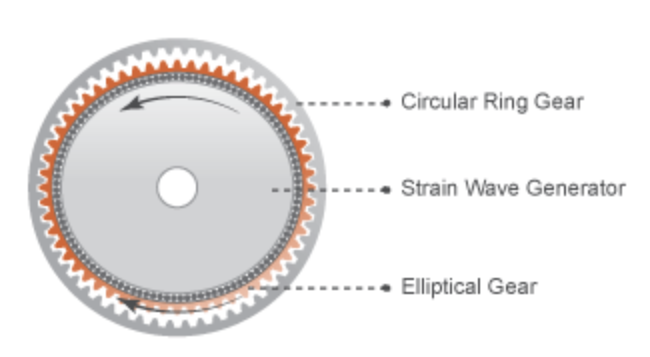

syms n_c % is the tooth number of the circular ring gear.
syms n_e % is the tooth number of the deformable elliptical gear.
syms k % reductio ratio (unknown)

optimal_constraint = n_e == n_c + 2 

$$optimal\_constraint = n_{e}=n_{c}+2$$


harmonic_reductio_ratio = k == n_e/(n_c - n_e)

$$harmonic\_reductio\_ratio = k=\frac{n_{e}}{n_{c}-n_{e}}$$